% For Fig 4:
% adult+juven lob 6, juven crus 1-> YM PC5, PC6
% juven crus 1, juven crus 2, adult+juven lob 7 -> SC PC3

clear all, close all, clc

load('data/2017-08-31-ks_analysis.mat')
whos

  Name               Size               Bytes  Class     Attributes

  epm                1x1               841024  struct              
  exptAges           2x1                  244  cell                
  exptRegions        4x1                  512  cell                
  gr                 1x1               422265  struct              
  kstable          336x9             53448809  table               
  sc                 1x1               998745  struct              
  timestamp          1x20                  40  char                
  ym                 1x1              1731200  struct              



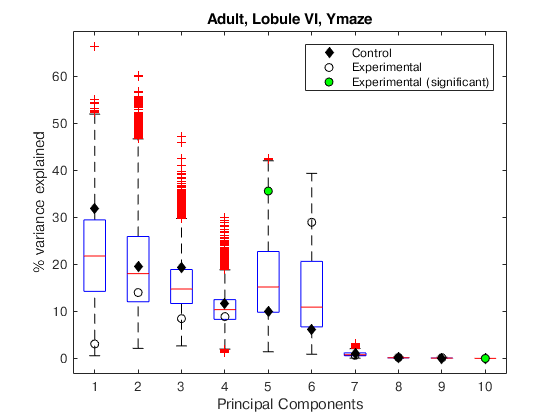

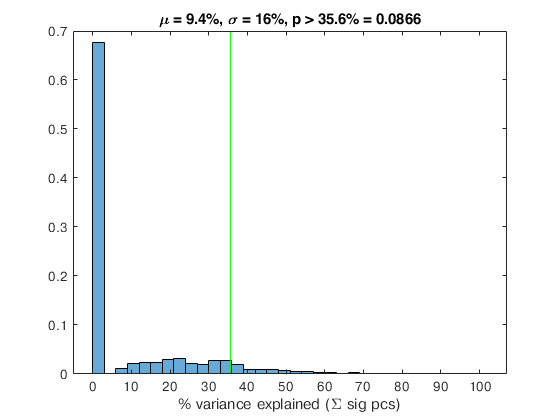

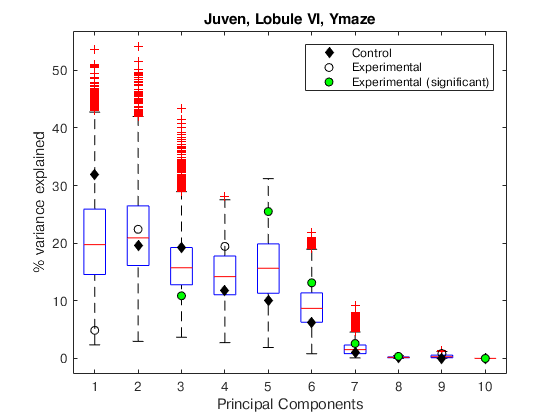

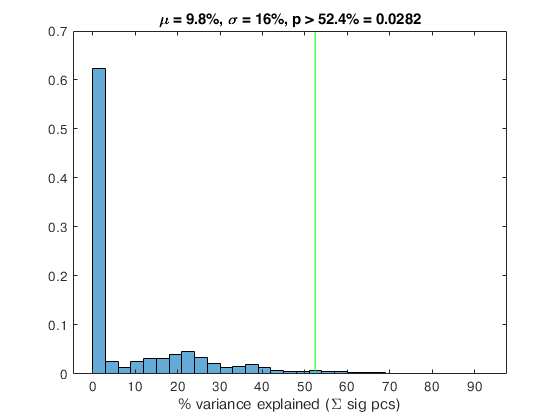

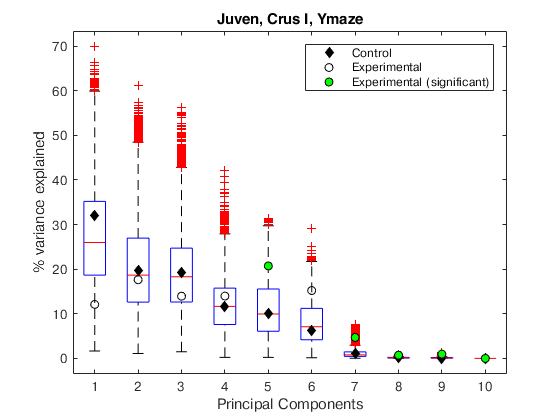

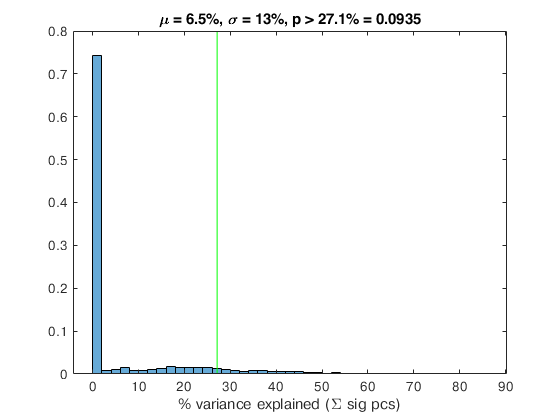

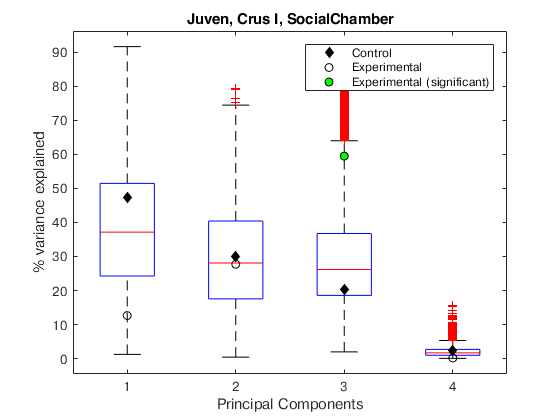

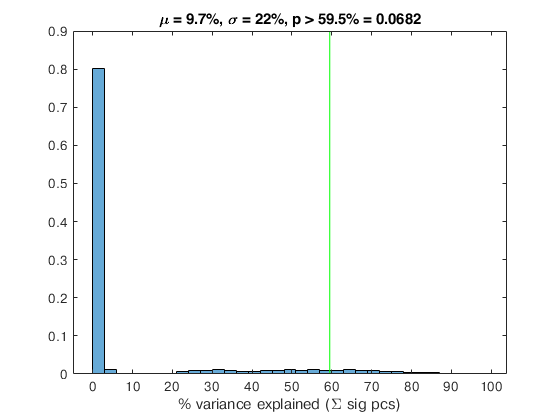

Bs = {
    ym.LobuleVI.Adult
    ym.LobuleVI.Juven
    ym.CrusI.Juven
    sc.CrusI.Juven
    sc.CrusII.Juven
    sc.LobuleVII.Adult
    sc.LobuleVII.Juven
};

for i = 1:numel(Bs)
    run_shuffle(Bs{i})
end

function run_shuffle(B, sig_var_perc_thresh)
if nargin < 2; sig_var_perc_thresh = []; end

% already normalized/projected:
allmice_amps = B.pca{:,:};
untreat_amps = B.pca{B.isCtrl,:}; % controls
treated_amps = B.pca{~B.isCtrl,:}; % experimentals

num_untreat = size(untreat_amps,1);
num_treated = size(treated_amps,1);
d = size(allmice_amps,2); % number of pcs

% latent (eigenvalues of covariance)
untreat_latent = sum(untreat_amps .^ 2) ./ size(untreat_amps,1);
treated_latent = sum(treated_amps .^ 2) ./ size(treated_amps,1);

% percent variance explained
untreat_var_perc = untreat_latent ./ sum(untreat_latent) .* 100;
treated_var_perc = treated_latent ./ sum(treated_latent) .* 100;

N = 10000; % number of bootstrap samples
% k = size(untreat_amps,1); % number of control mice per sample
k = size(treated_amps,1); % number of experimental mice per sample
alpha = 0.05; % significance level

% repeat procedure with data for reference
[~,treated_pval] = ttest2(untreat_amps,treated_amps); % significance test
treated_is_sig = treated_pval < alpha;
treated_sig_var = sum(treated_latent(treated_is_sig));
treated_sig_var_perc = treated_sig_var / sum(treated_latent) * 100;

% bootstrap
% tic;
sample_pval = NaN(N,d);
sample_var = NaN(N,d);
sample_sig_var = NaN(N,1);
sample_num_sig = NaN(N,1);
for i = 1:N
    sample_amps = datasample(allmice_amps,k); % random subsample
    sample_latent = sum(sample_amps .^ 2) ./ size(sample_amps,1); % compute latents (eigenvalues of covariance matrix)
    
    [~,sample_pval(i,:)] = ttest2(untreat_amps,sample_amps); % significance test
    is_sig = sample_pval(i,:) < alpha;
    
    sample_var(i,:) = sample_latent; % variance per pc
    sample_sig_var(i) = sum(sample_latent(is_sig)); % sum of variance for significant pcs
    sample_num_sig(i) = sum(is_sig); % count of significant pcs
end
% toc

% compute percent variance
sample_var_perc = sample_var ./ sum(sample_var,2) * 100;
sample_sig_var_perc = sample_sig_var ./ sum(sample_var,2) * 100;

% Plot
figure,boxplot(sample_var_perc), hold on
h1 = plot(1:d, untreat_var_perc, 'dk', 'MarkerSize',6, 'MarkerFaceColor','k');
h2 = plot(1:d, treated_var_perc, 'ok', 'MarkerSize',6);
h3 = plot(find(treated_is_sig), treated_var_perc(treated_is_sig), 'ok', 'MarkerSize',6, 'MarkerFaceColor','g');
xlabel('Principal Components'),ylabel('% variance explained')
legend([h1 h2 h3],{'Control', 'Experimental', 'Experimental (significant)'})
title(sprintf('%s, %s, %s', B.age_name, B.region_desc, B.assay_name))

% default to empirically computed
if isempty(sig_var_perc_thresh); sig_var_perc_thresh = treated_sig_var_perc; end

figure,histogram(sample_sig_var_perc, 'Normalization','probability'),hold on
plot([1 1] * sig_var_perc_thresh, ylim(), 'g-')
xlabel('% variance explained (\Sigma sig pcs)')
title(sprintf('\\mu = %.1f%%, \\sigma = %1.f%%, p > %.1f%% = %g', ...
    mean(sample_sig_var_perc), std(sample_sig_var_perc), ...
    sig_var_perc_thresh, mean(sample_sig_var_perc > sig_var_perc_thresh)))

end